Incremental Anomaly Detection 

Split the training data into 2 half.

load features.mat
feaTrain1 = feaTrain([1:30,331:360],:)

feaTrain1 = 60×7 table
        label         data_ps_spec/PeakAmp3    data_ps_spec/PeakAmp4    data_ps_spec/PeakAmp5    data_ps_spec/PeakAmp6    data_ps_spec/PeakAmp7    data_ps_spec/BandPower
    ______________    _____________________    _____________________    _____________________    _____________________    _____________________    ______________________

    InnerRaceFault         0.00083332               0.00081439               0.00080294               0.00072909               0.00071383                    4.27        
    InnerRaceFault          0.0012205                0.0011876                0.0010295               0.00098555               0.00095191                  3.6811        
    InnerRaceFault         0.00098629               0.0008

feaTrain([1:30,331:360,201:230],:)=[];
feaTrain2 = feaTrain(randperm(height(feaTrain)),:);
rng(0,"twister"); % For reproducibility
feaTrain1 = feaTrain1(randperm(height(feaTrain1)),:);
feaTrain2 = feaTrain2(randperm(height(feaTrain2)),:);

## Train SVM Model

Fit a naive Bayes classification model to the entire data set.

IncrementalMdl = incrementalClassificationECOC("MaxNumClasses",3,"MetricsWarmupPeriod",20)

IncrementalMdl =   incrementalClassificationECOC

            IsWarm: 0
           Metrics: [1×2 table]
        ClassNames: [1×0 double]
    ScoreTransform: 'none'
    BinaryLearners: {3×1 cell}
        CodingName: 'onevsone'
          Decoding: 'lossweighted'


  Properties, Methods


IncrementalMdl = fit(IncrementalMdl,feaTrain1{:,2:end},feaTrain1{:,1})

IncrementalMdl =   incrementalClassificationECOC

            IsWarm: 0
           Metrics: [1×2 table]
        ClassNames: [InnerRaceFault    Normal]
    ScoreTransform: 'none'
    BinaryLearners: {3×1 cell}
        CodingName: 'onevsone'
          Decoding: 'lossweighted'


  Properties, Methods


Estimate the confusion matrix for TTMdl.

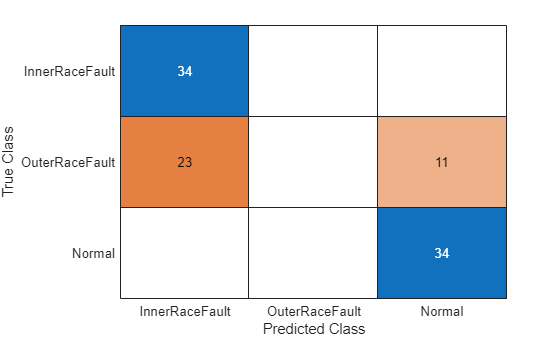

YPred1 = predict(IncrementalMdl,feaTest{:,2:end});
figure
ConfusionMatTest1 = confusionchart(feaTest{:,1},YPred1);

The model does not have the capability yet.

Incremental fitting with a few normal observation

% Incremental fitting
rng(0,"twister"); % For reproducibility

nil = height(feaTrain2);
numObsPerChunk = 10;
nchunk = floor(nil/numObsPerChunk);
mc = array2table(zeros(nchunk,2),VariableNames=["Cumulative","Window"]);
beta11 = zeros(nchunk+1,1);  
testaccuracy = zeros(nchunk,1);
% Incremental fitting
for j = 1:nchunk
    ibegin = min(nil,numObsPerChunk*(j-1) + 1);
    iend   = min(nil,numObsPerChunk*j);
    idx = ibegin:iend;    
    IncrementalMdl = updateMetricsAndFit(IncrementalMdl,feaTrain2{idx,2:end},feaTrain2{idx,1});
    mc{j,:} = IncrementalMdl.Metrics{"ClassificationError",:};
    beta11(j) = IncrementalMdl.BinaryLearners{1}.Beta(1);
    YPred2Temp = predict(IncrementalMdl,feaTest{:,2:end});
    testaccuracy(j)= sum(YPred2Temp==feaTest{:,1})/height(feaTest);
end

Plot the performance metrics and *μ*12 evolve during training, plot them on separate tiles.

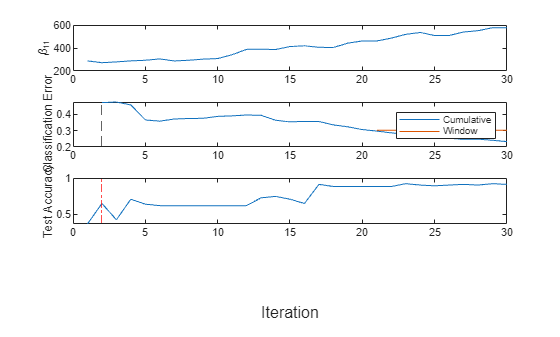

t = tiledlayout(4,1);
nexttile
plot(beta11)
ylabel("\beta_{11}")
xlim([0 nchunk])
nexttile
plot(mc.Variables)
xlim([0 nchunk])
ylabel("Classification Error")
xline(IncrementalMdl.MetricsWarmupPeriod/numObsPerChunk,"--")
legend(mc.Properties.VariableNames)
xlabel(t,"Iteration")
nexttile
h = plot(testaccuracy);
xlim([0 nchunk]);
ylabel('Test Accuracy')
xline(IncrementalMdl.MetricsWarmupPeriod/numObsPerChunk,'r-.');
xlabel(t,'Iteration')

Test obtained model

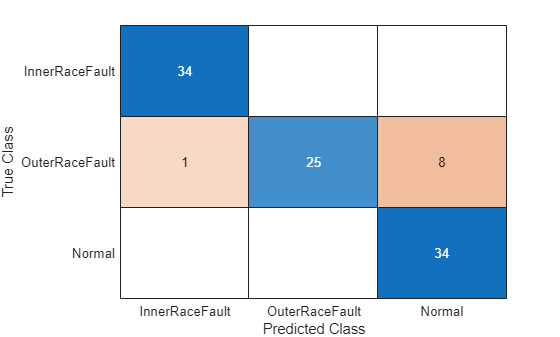

figure
YPred2 = predict(IncrementalMdl,feaTest{:,2:end});
ConfusionMatTest2 = confusionchart(feaTest{:,1},YPred2);